f=@(x) sin(x)*x.^5;
df=derivative(f);
u=@(x) f(x)/df(x);
h=@(x) x-f(x)/df(x);

newton=[];newton_multi=[];newton_multi_2=[];steff=[];
my_error=0.0001:0.0002:0.1;
for error=my_error
    x=2;
    [x,num]=newton_method(f,x,error,1);
    newton=[newton,num];
  
    x=2;
    [x,num]=newton_method(f,x,error,6);
    newton_multi=[newton_multi,num];
    
    x=2;
    [x,num]=newton_method(u,x,error,1);
    newton_multi_2=[newton_multi_2,num];
    
    x=2;
    [x,num]=steffenson(h,x,error);
    steff=[steff,num];
end

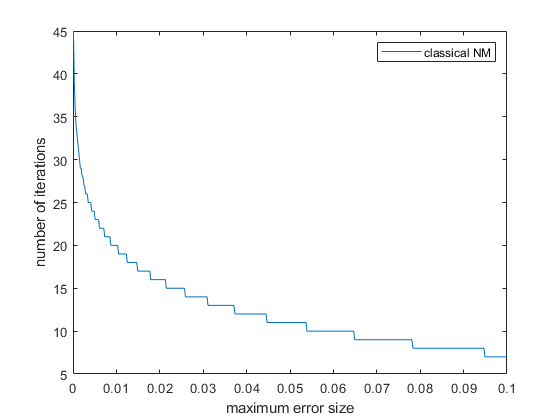

plot(my_error,newton)
legend('classical NM')
xlabel("maximum error size")
ylabel("number of iterations")

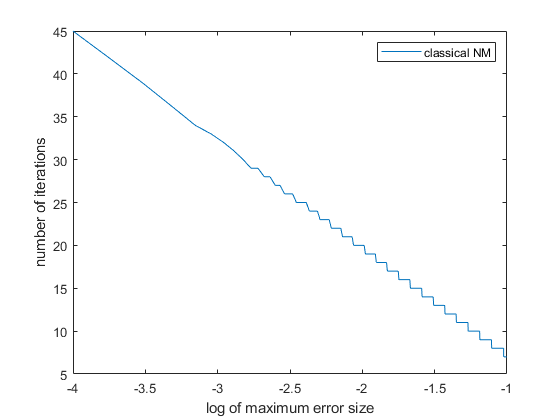

plot(log10(my_error),newton) %log(my_error) is natural logarithm
legend('classical NM')
xlabel("log of maximum error size")
ylabel("number of iterations")

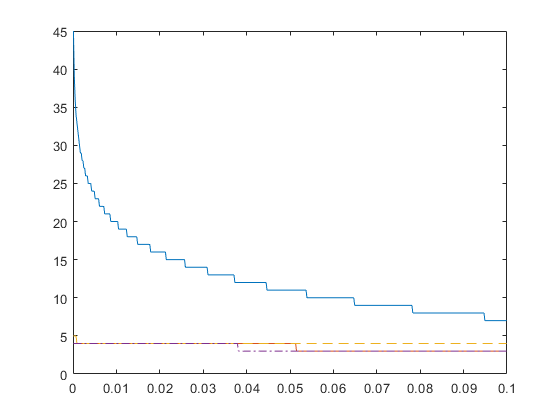

plot(my_error,newton,my_error,newton_multi,my_error,newton_multi_2,'--',my_error,steff,'-.')

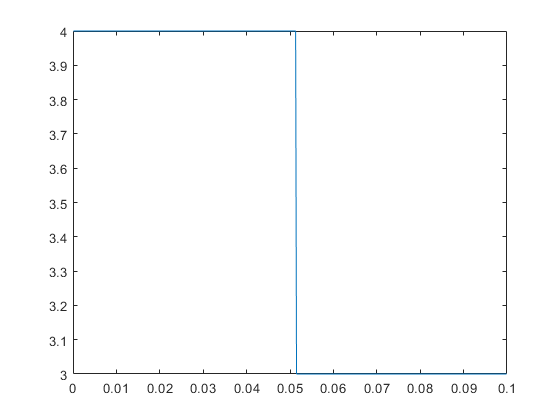

legend('classical NM','known multiplicity NM','unknown multiplicity NM','Steffenson')
plot(my_error,newton_multi)

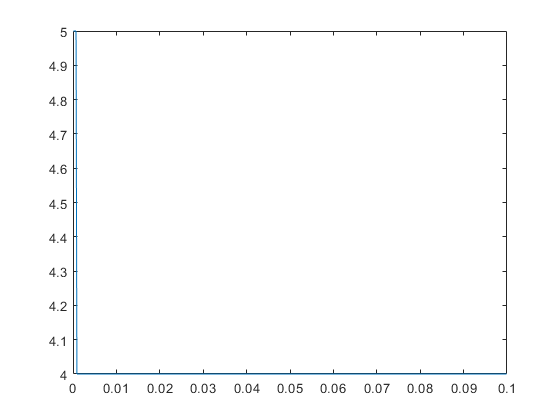

plot(my_error,newton_multi_2)

plot(my_error,steff)

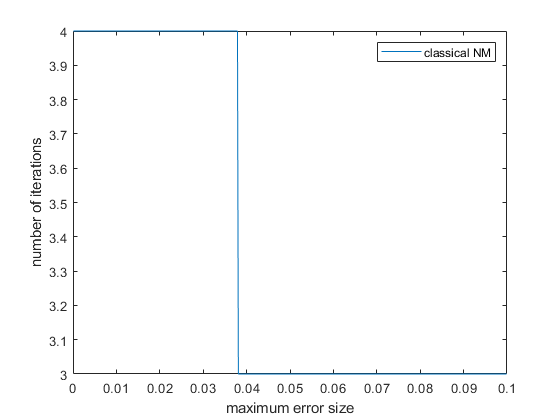

xlabel("maximum error size")
ylabel("number of iterations")

function [x,num] = newton_method(f,x,error,M)
%Newton method
x_prev=Inf;
df=derivative(f);
num=0;
while abs(x-x_prev)>error
    x_prev=x;
    x=x-M*f(x)/df(x);
    num=num+1;
end
end

function [x,num] = steffenson(g,x0,error)
% Steffenson method
x=Inf;
xnew=x0;
num=0;
while (abs(xnew-x)>error)
    x=xnew;
    y=g(x);
    z=g(y);
    xnew=x-(y-x)^2/(z-2*y+x);
    num=num+1;
end
x=xnew;
end